# Project 1 : Suspension Analysis

**Project summary : **This live script analyzes experimental suspension data to compare ride quality at low and high excitation frequencies. Raw sensor voltage data is converted into physical position and acceleration signals, processed, and analyzed using statistical metrics.

- Import and visualize raw experimental data (Code + Plots)

load suspensionData.mat
time = time1

time =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450
    0.0500
    0.0550
    0.0600
    0.0650
    0.0700


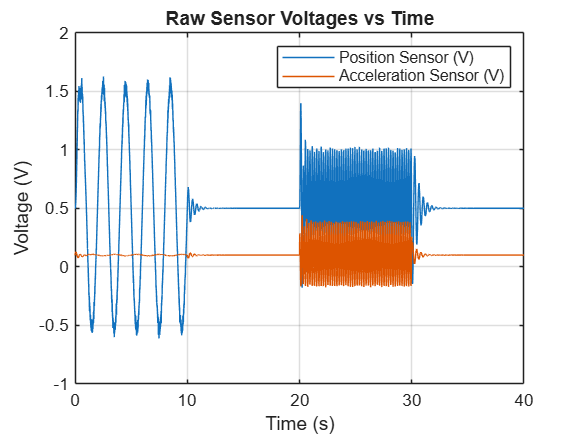

% Sampling period and frequency
Ts = time(2) - time(1);    % seconds
Fs = 1/Ts;                % Hz

figure
plot(time, Vpos, 'DisplayName','Position Sensor (V)'); 
hold on
plot(time, Vacc, 'DisplayName','Acceleration Sensor (V)');
xlabel('Time (s)')
ylabel('Voltage (V)')
title('Raw Sensor Voltages vs Time')
legend
grid on

       2. Data Preparation and Preprocessing                      (Coversion, Indexing, TestTime)

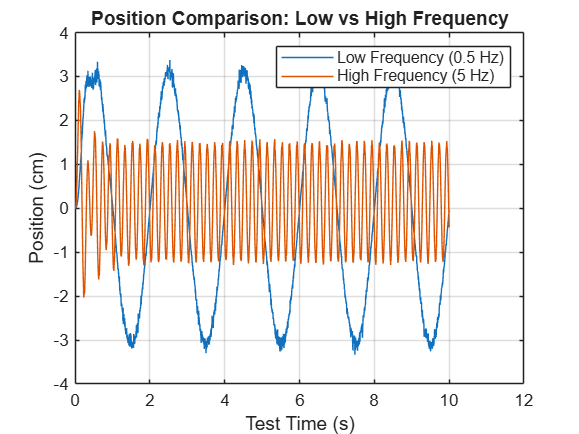

% Convert sensor voltages to physical quantities
pos = 3.00*(Vpos - 0.5);   % cm
acc = 5.09*(Vacc - 0.1);   % G

% Extract low-frequency (0.5 Hz) test data
posLow = pos(1:2001);
accLow = acc(1:2001);

% Extract high-frequency (5 Hz) test data
posHigh = pos(4001:6001);
accHigh = acc(4001:6001);

% Create time vector for one test
testTime = (0:length(posLow)-1)' * Ts;

figure
plot(testTime, posLow, 'DisplayName','Low Frequency (0.5 Hz)'); hold on
plot(testTime, posHigh,'DisplayName','High Frequency (5 Hz)');
xlabel('Test Time (s)')
ylabel('Position (cm)')
title('Position Comparison: Low vs High Frequency')
legend
grid on

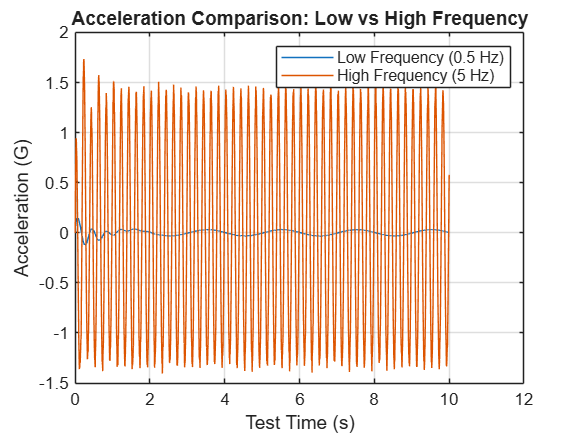


figure
plot(testTime, accLow, 'DisplayName','Low Frequency (0.5 Hz)'); hold on
plot(testTime, accHigh,'DisplayName','High Frequency (5 Hz)');
xlabel('Test Time (s)')
ylabel('Acceleration (G)')
title('Acceleration Comparison: Low vs High Frequency')
legend
grid on

         3. Statistical Analysis of Suspension Responses (RMS, Comparison, Plots )

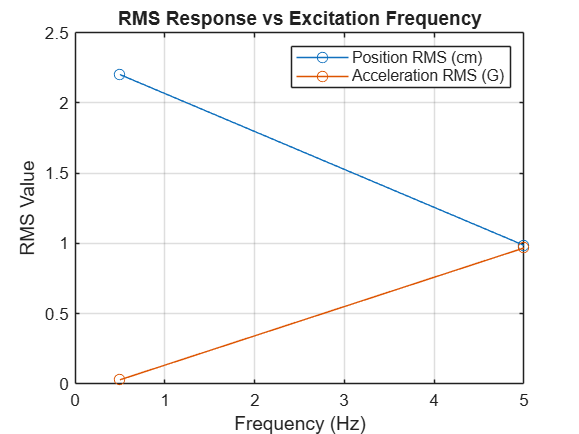

% RMS calculation for position
posLowRMS  = sqrt(mean(posLow.^2));
posHighRMS = sqrt(mean(posHigh.^2));

% RMS calculation for acceleration
accLowRMS  = sqrt(mean(accLow.^2));
accHighRMS = sqrt(mean(accHigh.^2));

testFreq = [0.5  5];

posRMS = [posLowRMS  posHighRMS];
accRMS = [accLowRMS  accHighRMS];

figure
plot(testFreq, posRMS, '-o', 'DisplayName','Position RMS (cm)'); hold on
plot(testFreq, accRMS, '-o', 'DisplayName','Acceleration RMS (G)');
xlabel('Frequency (Hz)')
ylabel('RMS Value')
title('RMS Response vs Excitation Frequency')
legend
grid on

**3.1. Extended performance matrics and comparative analysis:**

*To further characterize the suspension response beyond basic RMS values, additional time-domain and statistical metrics were evaluated. These include peak and peak-to-peak responses, relative RMS changes, and a combined comfort index to better capture ride quality differences across excitation frequencies.*

% RMS ratios and percent change (high vs low)
posRMS_ratio = posHighRMS / posLowRMS;
accRMS_ratio = accHighRMS / accLowRMS;

posRMS_pctChange = (posHighRMS - posLowRMS) / posLowRMS * 100;   % %
accRMS_pctChange = (accHighRMS - accLowRMS) / accLowRMS * 100;   % %

%Peak and peak-to-peak metrics (time-domain severity)
posLow_peakAbs  = max(abs(posLow));
posHigh_peakAbs = max(abs(posHigh));
accLow_peakAbs  = max(abs(accLow));
accHigh_peakAbs = max(abs(accHigh));

posLow_p2p  = max(posLow)  - min(posLow);
posHigh_p2p = max(posHigh) - min(posHigh);
accLow_p2p  = max(accLow)  - min(accLow);
accHigh_p2p = max(accHigh) - min(accHigh);

%Custom Comfort Index (creative metric combining displacement + acceleration)
comfortIndexLow  = posLowRMS  * accLowRMS;
comfortIndexHigh = posHighRMS * accHighRMS;

%Create a neat summary table
Summary = table( ...
    [0.5; 5], ...
    [posLowRMS; posHighRMS], ...
    [accLowRMS; accHighRMS], ...
    [posLow_peakAbs; posHigh_peakAbs], ...
    [accLow_peakAbs; accHigh_peakAbs], ...
    [posLow_p2p; posHigh_p2p], ...
    [accLow_p2p; accHigh_p2p], ...
    [comfortIndexLow; comfortIndexHigh], ...
    'VariableNames', {'Freq_Hz','Pos_RMS_cm','Acc_RMS_G','Pos_PeakAbs_cm','Acc_PeakAbs_G','Pos_P2P_cm','Acc_P2P_G','ComfortIndex'} ...
);

Summary

Summary = 2×8 table
    Freq_Hz    Pos_RMS_cm    Acc_RMS_G    Pos_PeakAbs_cm    Acc_PeakAbs_G    Pos_P2P_cm    Acc_P2P_G    ComfortIndex
    _______    __________    _________    ______________    _____________    __________    _________    ____________

      0.5         2.201      0.029675         3.3746           0.14652         6.7104       0.27111       0.065314  
        5        0.9864       0.96755         2.6932            1.7349         4.7258        3.1391        0.95439  


**3.2. Comparative Time-Domain Response Visualization:**

*To visually compare suspension behavior under low- and high-frequency excitation, the position and acceleration responses are plotted together using aligned subplots. This allows direct assessment of motion amplitude and vibration severity.*

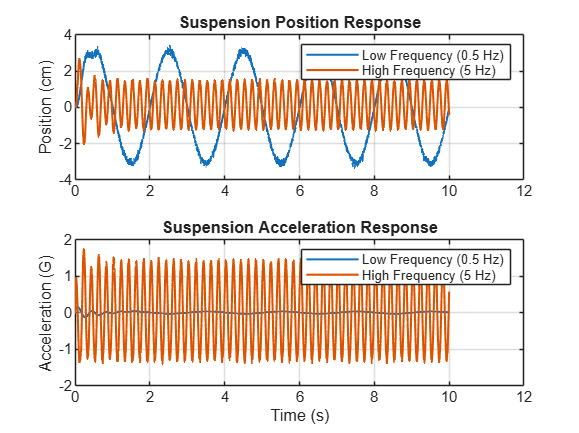

figure

subplot(2,1,1)
plot(testTime, posLow, 'LineWidth', 1.2);
hold on
plot(testTime, posHigh, 'LineWidth', 1.2)
ylabel('Position (cm)')
title('Suspension Position Response')
legend('Low Frequency (0.5 Hz)','High Frequency (5 Hz)')
grid on

subplot(2,1,2)
plot(testTime, accLow, 'LineWidth', 1.2); 
hold on
plot(testTime, accHigh, 'LineWidth', 1.2)
xlabel('Time (s)')
ylabel('Acceleration (G)')
title('Suspension Acceleration Response')
legend('Low Frequency (0.5 Hz)','High Frequency (5 Hz)')
grid on

**3.3. RMS based performance comparison across frequencies:**

*To clearly compare the suspension response across excitation frequencies, RMS values of position and acceleration are visualized using bar charts. This representation highlights the relative contribution of displacement and acceleration to ride quality.*

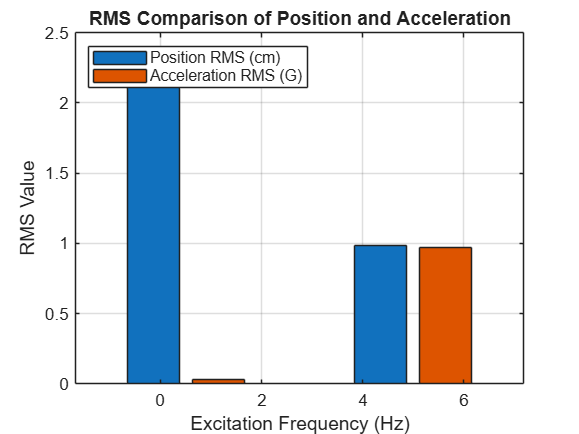

figure
bar(testFreq, [posRMS; accRMS]', 'grouped')
xlabel('Excitation Frequency (Hz)')
ylabel('RMS Value')
title('RMS Comparison of Position and Acceleration')
legend('Position RMS (cm)','Acceleration RMS (G)','Location','northwest')
grid on


% Display the summary table in a more readable format
disp('Summary of Suspension Response Metrics:');

Summary of Suspension Response Metrics:


disp(Summary);

    Freq_Hz    Pos_RMS_cm    Acc_RMS_G    Pos_PeakAbs_cm    Acc_PeakAbs_G    Pos_P2P_cm    Acc_P2P_G    ComfortIndex
    _______    __________    _________    ______________    _____________    __________    _________    ____________

      0.5         2.201      0.029675         3.3746           0.14652         6.7104       0.27111       0.065314  
        5        0.9864       0.96755         2.6932            1.7349         4.7258        3.1391        0.95439  



**3.4. Physical Interpretation of Frequency Effects:**

*The observed increase in acceleration response with excitation frequency can be explained by the frequency dependence of harmonic motion. For sinusoidal excitation, acceleration is proportional to the square of angular frequency (a ∝ ω²x). As a result, even when displacement amplitudes decrease at higher frequencies, the corresponding acceleration increases rapidly. This explains why high-frequency road inputs feel significantly harsher to passengers despite smaller visible suspension motion.*

omega = 2*pi*testFreq;   % angular frequency (rad/s)
omegaSquaredRatio = (omega(2)^2) / (omega(1)^2)

omegaSquaredRatio = 100

**Final Results:**

posLowRMS

posLowRMS = 2.2010

posHighRMS

posHighRMS = 0.9864

accLowRMS

accLowRMS = 0.0297

accHighRMS

accHighRMS = 0.9675

**4. Conclusion**

The suspension system was evaluated under low-frequency (0.5 Hz) and high-frequency (5 Hz) excitation using calibrated position and acceleration measurements. Ride quality was assessed using root-mean-square (RMS), peak, and peak-to-peak response metrics to quantify both sustained comfort levels and transient vibration severity.

At low-frequency excitation, the suspension exhibited larger displacement amplitudes, as reflected by a higher RMS position value. When the excitation frequency increased to 5 Hz, the RMS position decreased noticeably, indicating that the suspension moved less in terms of overall displacement. However, this reduction in displacement did not correspond to improved ride comfort.

In contrast, the acceleration response increased substantially with excitation frequency. The RMS acceleration at 5 Hz was several times higher than at 0.5 Hz, demonstrating that higher-frequency inputs generate significantly larger inertial forces. Peak and peak-to-peak acceleration values also increased markedly at high frequency, confirming a more severe and abrupt vibration response despite smaller suspension motion.

From a ride-quality perspective, these results clearly show that passenger discomfort is governed more by acceleration than by displacement. While low-frequency motion results in visible but relatively gentle suspension movement, high-frequency excitation produces rapid acceleration fluctuations that are more directly perceived by occupants and are commonly associated with ride harshness.

Overall, the analysis indicates that high-frequency road inputs degrade ride quality more severely than low-frequency inputs. Acceleration-based metrics were found to be more sensitive and informative than displacement-based metrics for evaluating ride comfort. Consequently, effective suspension design and tuning should prioritize the reduction of high-frequency acceleration transmission - through appropriate damping and vibration isolation - rather than focusing solely on limiting suspension displacement.

From an engineering standpoint, these results clearly indicate that **high-frequency excitation leads to poorer ride quality**, driven by significantly increased acceleration levels rather than displacement. Acceleration-based metrics therefore provide a more reliable and sensitive indicator of ride comfort than position-based metrics alone. Consequently, suspension design and tuning efforts should prioritize reducing high-frequency acceleration transmission- through damping optimization and vibration isolation - rather than focusing solely on limiting displacement amplitude.